clear
warning off
dbstop if error
tic
options=optimset("Display","off");
[kfasneg,eigenvalue]=deal(linspace(0.2,0.4,20));

a=0;
B=[linspace(0,0.49,50)]*complex(0,1);

for i = 1:length(kfasneg)
    eigenvalue(i)=borromeansolver(a,kfasneg(i),40/6,B(1));
    toc
    if eigenvalue(i)>0
        break
    end
end

时间已过 25.880191 秒。
时间已过 52.543131 秒。
时间已过 80.301039 秒。



eigs1=zeros(1,length(B));

eigs1(1)=fsolve(@(x) borromeansolver(a,x,40/6,B(1)),eigenvalue(i),options);
for i=2:length(eigs1)
    try
        eigs1(i)=fsolve(@(x) borromeansolver(a,x,40/6,B(i)),eigs1(i-1),options);
        toc
       
    catch ME
        eigs1=eigs1(1:i);
        
        B=B(1:i);
        break;
        
    end
end

时间已过 383.557299 秒。
时间已过 571.400315 秒。
时间已过 763.551329 秒。
时间已过 947.441995 秒。
时间已过 1130.649251 秒。
时间已过 1314.285740 秒。
时间已过 1496.753184 秒。
时间已过 1680.649886 秒。
时间已过 1864.039201 秒。
时间已过 2044.647737 秒。
时间已过 2231.342819 秒。
时间已过 2414.950848 秒。
时间已过 2598.971368 秒。
时间已过 2783.243813 秒。
时间已过 2964.752102 秒。
时间已过 3160.528634 秒。
时间已过 3346.033500 秒。
时间已过 3531.285567 秒。
时间已过 3717.662801 秒。
时间已过 3904.380472 秒。
时间已过 4089.280449 秒。
时间已过 4275.137695 秒。
时间已过 4459.630901 秒。
时间已过 4640.928667 秒。
时间已过 4826.306597 秒。
时间已过 5014.820442 秒。
时间已过 5208.073999 秒。
时间已过 5394.609702 秒。
时间已过 5575.216449 秒。
时间已过 5761.759630 秒。
时间已过 5955.497510 秒。
时间已过 6142.849578 秒。
时间已过 6326.253617 秒。
时间已过 6518.482535 秒。
时间已过 6703.086967 秒。
时间已过 6885.557774 秒。
时间已过 7067.454138 秒。
时间已过 7253.971927 秒。
时间已过 7437.326117 秒。
时间已过 7630.974062 秒。
时间已过 7818.792908 秒。
时间已过 8003.347431 秒。
时间已过 8187.290993 秒。
时间已过 8369.699555 秒。
时间已过 8563.308383 秒。
时间已过 8753.302195 秒。
时间已过 8939.562397 秒。
时间已过 9130.341229 秒。
时间已过 9315.666480 秒。


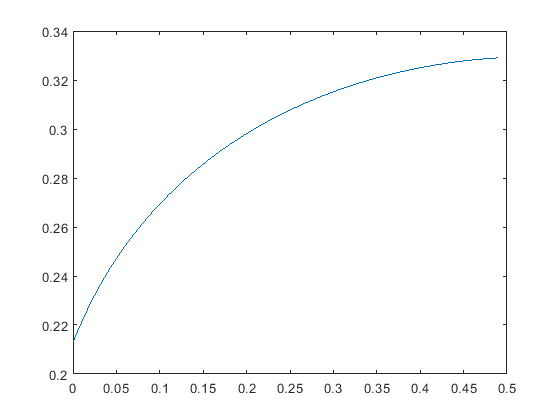

figure
plot(imag(B),eigs1)